# Figures of average acoustic features per bat

Playing around with all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
GGPath = dir('/Users/elie/Google Drive*');
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'MicAudioGood','CallType','OnSetOffsetSample',...
    'BatID', 'Duration','RMS_mean','Sal_mean',...
    'F0_mean','F0_cv','Spect_mean','Spect_std','Spect_kurt','Spect_skew','Spect_ent',...
    'Time_mean','Time_std','Time_kurt','Time_skew','Time_ent','SpectralMean_mean','Q1_mean','Q2_mean','Q3_mean','SpectMic_mean','SpectMic_std',...
    'SpectMic_kurt','SpectMic_skew','SpectMic_ent','Q1Mic_mean','Q2Mic_mean','Q3Mic_mean', 'AmpPeriodF','AmpPeriodP')
load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
MicAudioGoodInd = find(MicAudioGood01);
DurationElmt = diff(OnSetOffsetSample,1,2)/192000*1000;
fprintf(1,'In total, there are %d Vocal elements, %d are also of good microphone quality\n', length(MicAudioGood01), sum(MicAudioGood01))

In total, there are 36227 Vocal elements, 28091 are also of good microphone quality


Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for BatName, Sex and Deafness
GGPath = dir('/Users/elie/Google Drive*');
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Female';
    end

end
USexDeaf = {'Kanamycin Male' 'Saline Male' 'Kanamycin Female' 'Saline Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

Construct the table of PAF for statistical purposes

Tbl =  table(BatID(MicAudioGoodInd(TmicAll4==2)),...
    CallType(MicAudioGoodInd(TmicAll4==2)),...
    Sex(MicAudioGoodInd(TmicAll4==2)),...
    Deaf(MicAudioGoodInd(TmicAll4==2)),...
    DurationElmt(MicAudioGoodInd(TmicAll4==2)),...
    RMS_mean(MicAudioGoodInd(TmicAll4==2)),...
    Sal_mean(MicAudioGoodInd(TmicAll4==2)),...
    F0_mean(MicAudioGoodInd(TmicAll4==2))/1000,...
    F0_cv(MicAudioGoodInd(TmicAll4==2)),...
    Spect_mean(MicAudioGoodInd(TmicAll4==2))/10^3,...
    Spect_std(MicAudioGoodInd(TmicAll4==2))/10^3,...
    Spect_kurt(MicAudioGoodInd(TmicAll4==2)),...
    Spect_skew(MicAudioGoodInd(TmicAll4==2)),...
    Spect_ent(MicAudioGoodInd(TmicAll4==2)),...
    Time_mean(MicAudioGoodInd(TmicAll4==2)),...
    Time_std(MicAudioGoodInd(TmicAll4==2)),...
    Time_kurt(MicAudioGoodInd(TmicAll4==2)),...
    Time_skew(MicAudioGoodInd(TmicAll4==2)),...
    Time_ent(MicAudioGoodInd(TmicAll4==2)),...
    Q1_mean(MicAudioGoodInd(TmicAll4==2))/10^3,...
    Q2_mean(MicAudioGoodInd(TmicAll4==2))/10^3,...
    Q3_mean(MicAudioGoodInd(TmicAll4==2))/10^3,...
    SpectMic_mean(MicAudioGoodInd(TmicAll4==2))/10^3,...
    SpectMic_std(MicAudioGoodInd(TmicAll4==2))/10^3,...
    SpectMic_kurt(MicAudioGoodInd(TmicAll4==2)),...
    SpectMic_skew(MicAudioGoodInd(TmicAll4==2)),...
    SpectMic_ent(MicAudioGoodInd(TmicAll4==2)),...
    Q1Mic_mean(MicAudioGoodInd(TmicAll4==2))/10^3,...
    Q2Mic_mean(MicAudioGoodInd(TmicAll4==2))/10^3,...
    Q3Mic_mean(MicAudioGoodInd(TmicAll4==2))/10^3,...
    AmpPeriodF(MicAudioGoodInd(TmicAll4==2)),...
    AmpPeriodP(MicAudioGoodInd(TmicAll4==2)),...
    'VariableNames', {'BatID', 'CT','Sex','HorD',...
    'Duration (ms)','RMS mean','Saliency (AU)','F0 (kHz)','F0 CV','Spectral mean (kHz)','Spectral std (kHz)','Spectral kurtosis (Hz)','Spectral skewness (Hz)','Spectral entropy',...
    'Time mean (ms)','Time std (ms)','Time kurtosis (ms)','Time skewness (ms)','Time entropy','First quartile (kHz)','Second quartile (kHz)','Third quartile (kHz)','Mic Spectral mean (kHz)','Mic Spectral std (kHz)',...
    'Mic Spectral kurtosis (Hz)','Mic Spectral skewness (Hz)','Mic Spectral entropy','Mic First quartile (kHz)','Mic Second quartile (kHz)','Mic Third quartile (kHz)','Amplitude Periodicity F (Hz)','Amplitude Periodicity P'});
Tbl.HorD = categorical(Tbl.HorD, {'H' 'D'});

Go through all acoustic categories and calculate and plot the average values of features for all individuals

% List of variables
AcVars = Tbl.Properties.VariableNames(5:end);
Pvalue_matrix_Post_hoc = nan(length(AcVars),1);
BatMales = BatName(contains(BatSexDeaf, 'Male'));
BatSexDeafMales = BatSexDeaf(contains(BatSexDeaf, 'Male'));
Fig1=figure(1);
clf
T=tiledlayout(4,7,'TileSpacing','compact');
set(gcf,'Visible','on')
INN = contains(Tbl.Sex, 'M');
for vv=1:length(AcVars)
    fprintf(1, '*********************     Calculations on %s   ********************\n', AcVars{vv})
    AcVar = Tbl.(sprintf('%s',AcVars{vv}));
    Tbl_local = table(Tbl.BatID(INN), Tbl.CT(INN), Tbl.HorD(INN), AcVar(INN), 'VariableNames', {'BatID', 'CT','HorD', 'AcVar'});
    Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});

    % Full Model
    lme = fitlme(Tbl_local, 'AcVar ~ HorD + (1|BatID)');
    % Reduced model without deafening fixed effect
    lmeR = fitlme(Tbl_local, 'AcVar ~ 1 + (1|BatID)');
    TestLME_HD=compare(lmeR, lme)
    Pvalue_matrix_Post_hoc(vv) = TestLME_HD.pValue(2);

    lme

    % Nice plot 1
    AcVar_mean_pBat = nan(size(BatMales));
    AcVar_se_pBat = nan(size(BatMales));
    Col_local = nan(length(BatMales),3);
    for bb=1:length(BatMales)
        Ind = INN(strcmp(Tbl.BatID(INN),num2str(BatMales(bb))));
        
        AcVar_mean_pBat(bb) = mean(AcVar(Ind), 'omitnan');
        AcVar_se_pBat(bb) = std(AcVar(Ind), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
        Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeafMales{bb}),:);
    end

   
    AcVarMean_HD = [mean(AcVar_mean_pBat(contains(BatSexDeafMales, 'Kanamycin'))) mean(AcVar_mean_pBat(contains(BatSexDeafMales, 'Saline')))];
    AcVarSE_HD = [std(AcVar_mean_pBat(contains(BatSexDeafMales, 'Kanamycin')))/sum(contains(BatSexDeafMales, 'Kanamycin'))^0.5 std(AcVar_mean_pBat(contains(BatSexDeafMales, 'Saline')))/sum(contains(BatSexDeafMales, 'Saline'))^0.5];
    
    N=nexttile(vv,[1,1]);
    XHorD = [0.5 1.5 2.5 3.5];
%     XHorD(contains(BatSexDeafMales, 'Saline')) = XHorD(contains(BatSexDeafMales, 'Saline'))+2;
    errorbar([1 3],AcVarMean_HD, 2*AcVarSE_HD, 2*AcVarSE_HD, 'k.','LineWidth',2)
    hold on
    B=bar([1 3], AcVarMean_HD);
    B.FaceColor = 'flat';
    B.CData(1,:) = 0.8*ones(1,3);
    B.CData(2,:) = ones(1,3);
    hold on
    errorbar(XHorD,AcVar_mean_pBat, 2*AcVar_se_pBat, 2*AcVar_se_pBat, 'k.','LineWidth',2)
    hold on
    scatter(XHorD,AcVar_mean_pBat,100, Col_local, 'filled')
    ylabel(sprintf('%s', AcVars{vv}), 'FontSize',12)
    XLim = [0 4];
    set(gca, 'XLim', XLim);
    YLim = get(gca, 'YLim');
    MinVal = min(AcVar_mean_pBat-2*AcVar_se_pBat);
    MaxVal = max(AcVar_mean_pBat+2*AcVar_se_pBat);
    YLim = [MinVal - (MaxVal-MinVal)/3 MaxVal + (MaxVal-MinVal)/3];
%     YLim(1) = MinVal - (MaxVal-MinVal)*2/3;
    set(gca, 'YLim', YLim)
%     if vv==length(AcVars)
%         for ct=1:length(USexDeaf(1:2))
%             text(4,YLim(2)-diff(YLim)*(2+ct)/10, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
%         end
%     end
    if vv>21
        set(gca, 'XTick', [1 3],'XTickLabel', {'Kanamycin' 'Saline'}, 'FontSize',12)
    else
        set(gca, 'XTick', [1 3],'XTickLabel', {'' ''})
    end
    YTick= get(gca, 'YTick');
    set(gca,'YTick', [YTick(1) YTick(end)], 'FontSize',10)
    hold off
    if ~(TestLME_HD.pValue(2) <0.01)
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
%         T.FontWeight = 'normal';
%         T.Color = 0.7.*ones(1,3);
    else
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        hold on
        plot([1 3], (18/20*diff(YLim) + YLim(1)).*ones(1,2), '-','Color','k', 'LineWidth',2)
        hold on
        text(2,(19/20*diff(YLim) + YLim(1)), '<.01','FontSize', 9)
    end
    N.Box = 0;
    

    %         nexttile
    %         errorbar(XHorD,AcVar_meanse_pBat_sexnorm(:,1), 2*AcVar_meanse_pBat_sexnorm(:,2), 2*AcVar_meanse_pBat_sexnorm(:,2), 'k.')
    %         hold on
    %         scatter(XHorD,AcVar_meanse_pBat_sexnorm(:,1),100, Col_local, 'filled')
    %         ylabel(sprintf('%s (z-scored)', AcVars{vv}))
    %         XLim = [0 4];
    %         set(gca, 'XLim', XLim);
    %         YLim = get(gca, 'YLim');
    %         for ct=1:length(USexDeaf)
    %             text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
    %         end
    %         set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
    %         hold off
    %         title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))


end

*********************     Calculations on Duration (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     3     51317    51336    -25655                                
    lme      4     51317    51343    -25655    1.5493    1          0.21324


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    51317    51343    -25655           51309   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat      DF      pValue        Lower      Upper 
    {'(Intercept)'}         53.843     3.0797     17.483    4751    2.2066e-66     47.806    59.881
    {'HorD_D'     }        -5.9455     4.4284    -1.3426    4751       0.17948    -14.627    2.7363

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower     

*********************     Calculations on RMS mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -10460    -10441      5233                                
    lme      4     -10460    -10434    5234.1    2.0198    1          0.15526


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -10460    -10434    5234.1           -10468  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat      DF      pValue        Lower        Upper    
    {'(Intercept)'}           0.1592    0.0082312     19.341    4751    2.7448e-80      0.14307      0.17534
    {'HorD_D'     }        -0.019044     0.011702    -1.6274    4751       0.10372    -0.041985    0.0038979

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type  

*********************     Calculations on Saliency (AU)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     3      -171.6    -152.32    88.801                                 
    lme      4     -170.23    -144.51    89.113    0.62304    1          0.42992


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4575
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -170.23    -144.51    89.113           -178.23 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat       DF      pValue        Lower       Upper   
    {'(Intercept)'}          0.63196    0.044001      14.362    4573    8.7185e-46      0.5457     0.71822
    {'HorD_D'     }        -0.051264    0.062333    -0.82242    4573       0.41088    -0.17347    0.070939

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type    

*********************     Calculations on F0 (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR     3     3720.9      3740    -1857.4                                 
    lme      4     3722.6    3748.1    -1857.3    0.23175    1          0.63023


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4290
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3722.6    3748.1    -1857.3          3714.6  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat       DF      pValue        Lower       Upper  
    {'(Intercept)'}          0.75095    0.096816      7.7564    4288    1.0841e-14     0.56114    0.94076
    {'HorD_D'     }        -0.066982     0.13704    -0.48878    4288       0.62502    -0.33565    0.20169

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           

*********************     Calculations on F0 CV   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue
    lmeR     3     -2561.2    -2542.1    1283.6                                
    lme      4     -2544.3    -2518.9    1276.2    -14.882    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4290
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -2544.3    -2518.9    1276.2           -2552.3 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue        Lower       Upper   
    {'(Intercept)'}        0.068991    0.0034133    20.212    4288    7.5349e-87    0.062299    0.075683
    {'HorD_D'     }        0.023213    0.0057381    4.0454    4288    5.3143e-05    0.011963    0.034463

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type          

*********************     Calculations on Spectral mean (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue
    lmeR     3     2794.3    2813.7    -1394.2                               
    lme      4     2794.2    2820.1    -1393.1    2.0969    1          0.1476


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2794.2    2820.1    -1393.1          2786.2  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue         Lower       Upper   
    {'(Intercept)'}          1.5569    0.070298     22.146    4751    1.6623e-103       1.419      1.6947
    {'HorD_D'     }        -0.16551    0.099533    -1.6629    4751         0.0964    -0.36064    0.029618

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           

*********************     Calculations on Spectral std (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lmeR     3     -1766.3    -1746.9    886.14                               
    lme      4     -1765.7    -1739.9    886.87    1.4496    1          0.2286


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -1765.7    -1739.9    886.87           -1773.7 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF      pValue     Lower        Upper   
    {'(Intercept)'}          0.83872    0.020003      41.93    4751          0       0.7995     0.87793
    {'HorD_D'     }        -0.037316    0.028445    -1.3119    4751    0.18963    -0.093082    0.018449

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Es

*********************     Calculations on Spectral kurtosis (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     3     43996    44015    -21995                                
    lme      4     43997    44022    -21994    1.4069    1          0.23558


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    43997    44022    -21994           43989   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF      pValue        Lower      Upper 
    {'(Intercept)'}        19.449      1.9454    9.9976    4751    2.6489e-23     15.635    23.263
    {'HorD_D'     }        3.6412      2.7758    1.3118    4751       0.18967    -1.8007    9.0832

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower     Upp

*********************     Calculations on Spectral skewness (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue 
    lmeR     3     18171    18190    -9082.3                                
    lme      4     18171    18197    -9081.7    1.09      1          0.29647


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    18171    18197    -9081.7          18163   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue       Lower       Upper  
    {'(Intercept)'}         2.4336     0.21593     11.27    4751    4.304e-29      2.0103     2.8569
    {'HorD_D'     }        0.34392     0.30634    1.1227    4751      0.26163    -0.25665    0.94449

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower  

*********************     Calculations on Spectral entropy   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lmeR     3     -6306.9    -6287.5    3156.4                               
    lme      4     -6305.1    -6279.3    3156.6    0.2753    1          0.5998


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -6305.1    -6279.3    3156.6           -6313.1 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue         Lower        Upper   
    {'(Intercept)'}         0.58959    0.015354       38.4    4751    3.1936e-281      0.55949     0.61969
    {'HorD_D'     }        0.011664    0.021792    0.53525    4751         0.5925    -0.031059    0.054387

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type    

*********************     Calculations on Time mean (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -23030    -23011    11518                                 
    lme      4     -23030    -23005    11519     2.1424    1          0.14327


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -23030    -23005    11519            -23038  

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE           tStat      DF      pValue        Lower         Upper     
    {'(Intercept)'}          0.024965    0.0013774     18.125    4751    4.7607e-71      0.022265      0.027665
    {'HorD_D'     }        -0.0032513    0.0019741    -1.6469    4751      0.099635    -0.0071215    0.00061892

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2               

*********************     Calculations on Time std (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -28454    -28434    14230                                 
    lme      4     -28454    -28428    14231     1.8492    1          0.17388


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -28454    -28428    14231            -28462  

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE           tStat     DF      pValue        Lower         Upper    
    {'(Intercept)'}          0.012212    0.0008592    14.213    4751    6.2742e-45      0.010527     0.013896
    {'HorD_D'     }        -0.0018513    0.0012285    -1.507    4751       0.13188    -0.0042597    0.0005571

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Typ

*********************     Calculations on Time kurtosis (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue  
    lmeR     3     11576    11595    -5784.9                                 
    lme      4     11575    11600    -5783.3    3.1122    1          0.077706


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11575    11600    -5783.3          11567   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue      Lower       Upper  
    {'(Intercept)'}         2.5521     0.054658    46.693    4751           0       2.445     2.6593
    {'HorD_D'     }        0.16616     0.078256    2.1232    4751    0.033787    0.012737    0.31957

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower  

*********************     Calculations on Time skewness (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     2453.1    2472.5    -1223.6                                
    lme      4     2453.7    2479.6    -1222.8    1.4179    1          0.23375


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2453.7    2479.6    -1222.8          2445.7  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat      DF      pValue        Lower        Upper    
    {'(Intercept)'}         0.066305    0.0056365     11.763    4751    1.6415e-31     0.055255     0.077355
    {'HorD_D'     }        -0.011324     0.009509    -1.1908    4751       0.23378    -0.029966    0.0073184

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type  

*********************     Calculations on Time entropy   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat     deltaDF    pValue
    lmeR     3     -16145    -16126    8075.7                                
    lme      4     -16140    -16115    8074.2    -2.9348    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -16140    -16115    8074.2           -16148  

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE           tStat      DF      pValue        Lower         Upper     
    {'(Intercept)'}           0.92111    0.0007971     1155.6    4751             0       0.91955       0.92267
    {'HorD_D'     }        -0.0064592    0.0013447    -4.8033    4751    1.6088e-06    -0.0090955    -0.0038229

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2               

*********************     Calculations on First quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -225.57    -206.17    115.78                                
    lme      4     -225.73    -199.87    116.87    2.168     1          0.14091


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4752
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -225.73    -199.87    116.87           -233.73 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue      Lower       Upper   
    {'(Intercept)'}         1.9258     0.033732     57.091    4750           0      1.8597      1.9919
    {'HorD_D'     }        -0.0815     0.047833    -1.7038    4750    0.088475    -0.17528    0.012275

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estim

*********************     Calculations on Second quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     6953.1    6972.5    -3473.6                                
    lme      4     6953.8    6979.7    -3472.9    1.323     1          0.25006


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4752
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    6953.8    6979.7    -3472.9          6945.8  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF      pValue     Lower       Upper   
    {'(Intercept)'}           3.8374    0.048787     78.657    4750          0      3.7418      3.9331
    {'HorD_D'     }        -0.087494      0.0694    -1.2607    4750    0.20747    -0.22355    0.048561

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate 

*********************     Calculations on Third quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue 
    lmeR     3     10382    10401    -5187.8                                
    lme      4     10383    10408    -5187.3    1.1339    1          0.28694


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4752
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    10383    10408    -5187.3          10375   

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF      pValue     Lower       Upper   
    {'(Intercept)'}           6.4884    0.056184     115.49    4750          0      6.3782      6.5985
    {'HorD_D'     }        -0.091753     0.08018    -1.1443    4750    0.25254    -0.24894    0.065436

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    L

*********************     Calculations on Mic Spectral mean (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat        deltaDF    pValue 
    lmeR     3     13662    13682    -6828.1                                    
    lme      4     13664    13690    -6828.1    1.0102e-05    1          0.99746


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    13664    13690    -6828.1          13656   

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE          tStat         DF      pValue     Lower        Upper   
    {'(Intercept)'}            1.7966    0.018331         98.01    4751          0       1.7607      1.8325
    {'HorD_D'     }        -9.829e-05    0.030925    -0.0031784    4751    0.99746    -0.060725    0.060528

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type         

*********************     Calculations on Mic Spectral std (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue  
    lmeR     3     17785    17804    -8889.5                                 
    lme      4     17783    17809    -8887.7    3.5722    1          0.058754


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    17783    17809    -8887.7          17775   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue         Lower       Upper  
    {'(Intercept)'}          3.455     0.10949    31.555    4751    1.3848e-198      3.2403     3.6696
    {'HorD_D'     }        0.37615     0.15661    2.4019    4751        0.01635    0.069126    0.68317

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    L

*********************     Calculations on Mic Spectral kurtosis (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     3     58341    58360    -29167                                 
    lme      4     58339    58365    -29165    4.0596    1          0.043921


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    58339    58365    -29165           58331   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'}         147.02     8.1033     18.144    4751    3.4701e-71     131.14     162.91
    {'HorD_D'     }        -30.742     11.581    -2.6546    4751     0.0079677    -53.446    -8.0382

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower  

*********************     Calculations on Mic Spectral skewness (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     3     27171    27190    -13582                                 
    lme      4     27169    27195    -13580    3.8498    1          0.049752


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    27169    27195    -13580           27161   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue         Lower      Upper  
    {'(Intercept)'}          10.18     0.29633     34.354    4751    3.3007e-231     9.5992     10.761
    {'HorD_D'     }        -1.0797     0.42378    -2.5478    4751       0.010872    -1.9105    -0.2489

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    L

*********************     Calculations on Mic Spectral entropy   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -8277.1    -8257.7    4141.6                                
    lme      4     -8276.5    -8250.7    4142.3    1.4224    1          0.23302


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4753
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -8276.5    -8250.7    4142.3           -8284.5 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue         Lower        Upper  
    {'(Intercept)'}         0.39977    0.011432     34.97    4751    1.2815e-238      0.37736    0.42218
    {'HorD_D'     }        0.021299    0.016237    1.3118    4751        0.18967    -0.010533    0.05313

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type          

*********************     Calculations on Mic First quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     3     20811    20830    -10402                                
    lme      4     20811    20837    -10402    1.3147    1          0.25154


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4752
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    20811    20837    -10402           20803   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower      Upper 
    {'(Intercept)'}         6.0447     0.27091    22.312    4750    5.861e-105     5.5136    6.5759
    {'HorD_D'     }        0.47795     0.38447    1.2431    4750       0.21388    -0.2758    1.2317

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower     

*********************     Calculations on Mic Second quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR     3     28877    28897    -14436                                 
    lme      4     28878    28904    -14435    0.96216    1          0.32664


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4752
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    28878    28904    -14435           28870   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue         Lower      Upper 
    {'(Intercept)'}         15.31      0.57994    26.399    4750    1.9844e-143     14.173    16.447
    {'HorD_D'     }        0.8554      0.82358    1.0386    4750        0.29903    -0.7592      2.47

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower  

*********************     Calculations on Mic Third quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR     3     33893    33912    -16943                                 
    lme      4     33894    33920    -16943    0.39633    1          0.52899


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4752
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    33894    33920    -16943           33886   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue         Lower      Upper 
    {'(Intercept)'}         29.264     0.77396    37.811    4750    9.6995e-274     27.747    30.782
    {'HorD_D'     }        0.70799      1.1019    0.6425    4750        0.52058    -1.4523    2.8683

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower  

*********************     Calculations on Amplitude Periodicity F (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    lmeR     3     60574    60594    -30284                                
    lme      4     60576    60602    -30284    0.34284    1          0.5582


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4715
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    60576    60602    -30284           60568   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat      DF      pValue     Lower      Upper 
    {'(Intercept)'}        164.31      2.6967      60.93    4713          0     159.03     169.6
    {'HorD_D'     }        2.6596      4.5422    0.58553    4713    0.55822    -6.2452    11.564

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower    Upper
    

*********************     Calculations on Amplitude Periodicity P   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -8919.6    -8900.2    4462.8                                
    lme      4     -8919.7    -8893.8    4463.8    2.0508    1          0.15213


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            4715
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -8919.7    -8893.8    4463.8           -8927.7 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat      DF      pValue        Lower        Upper    
    {'(Intercept)'}         0.046484    0.0089652     5.1849    4713    2.2514e-07     0.028908      0.06406
    {'HorD_D'     }        -0.020665     0.012755    -1.6201    4713       0.10528    -0.045671    0.0043418

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Ty

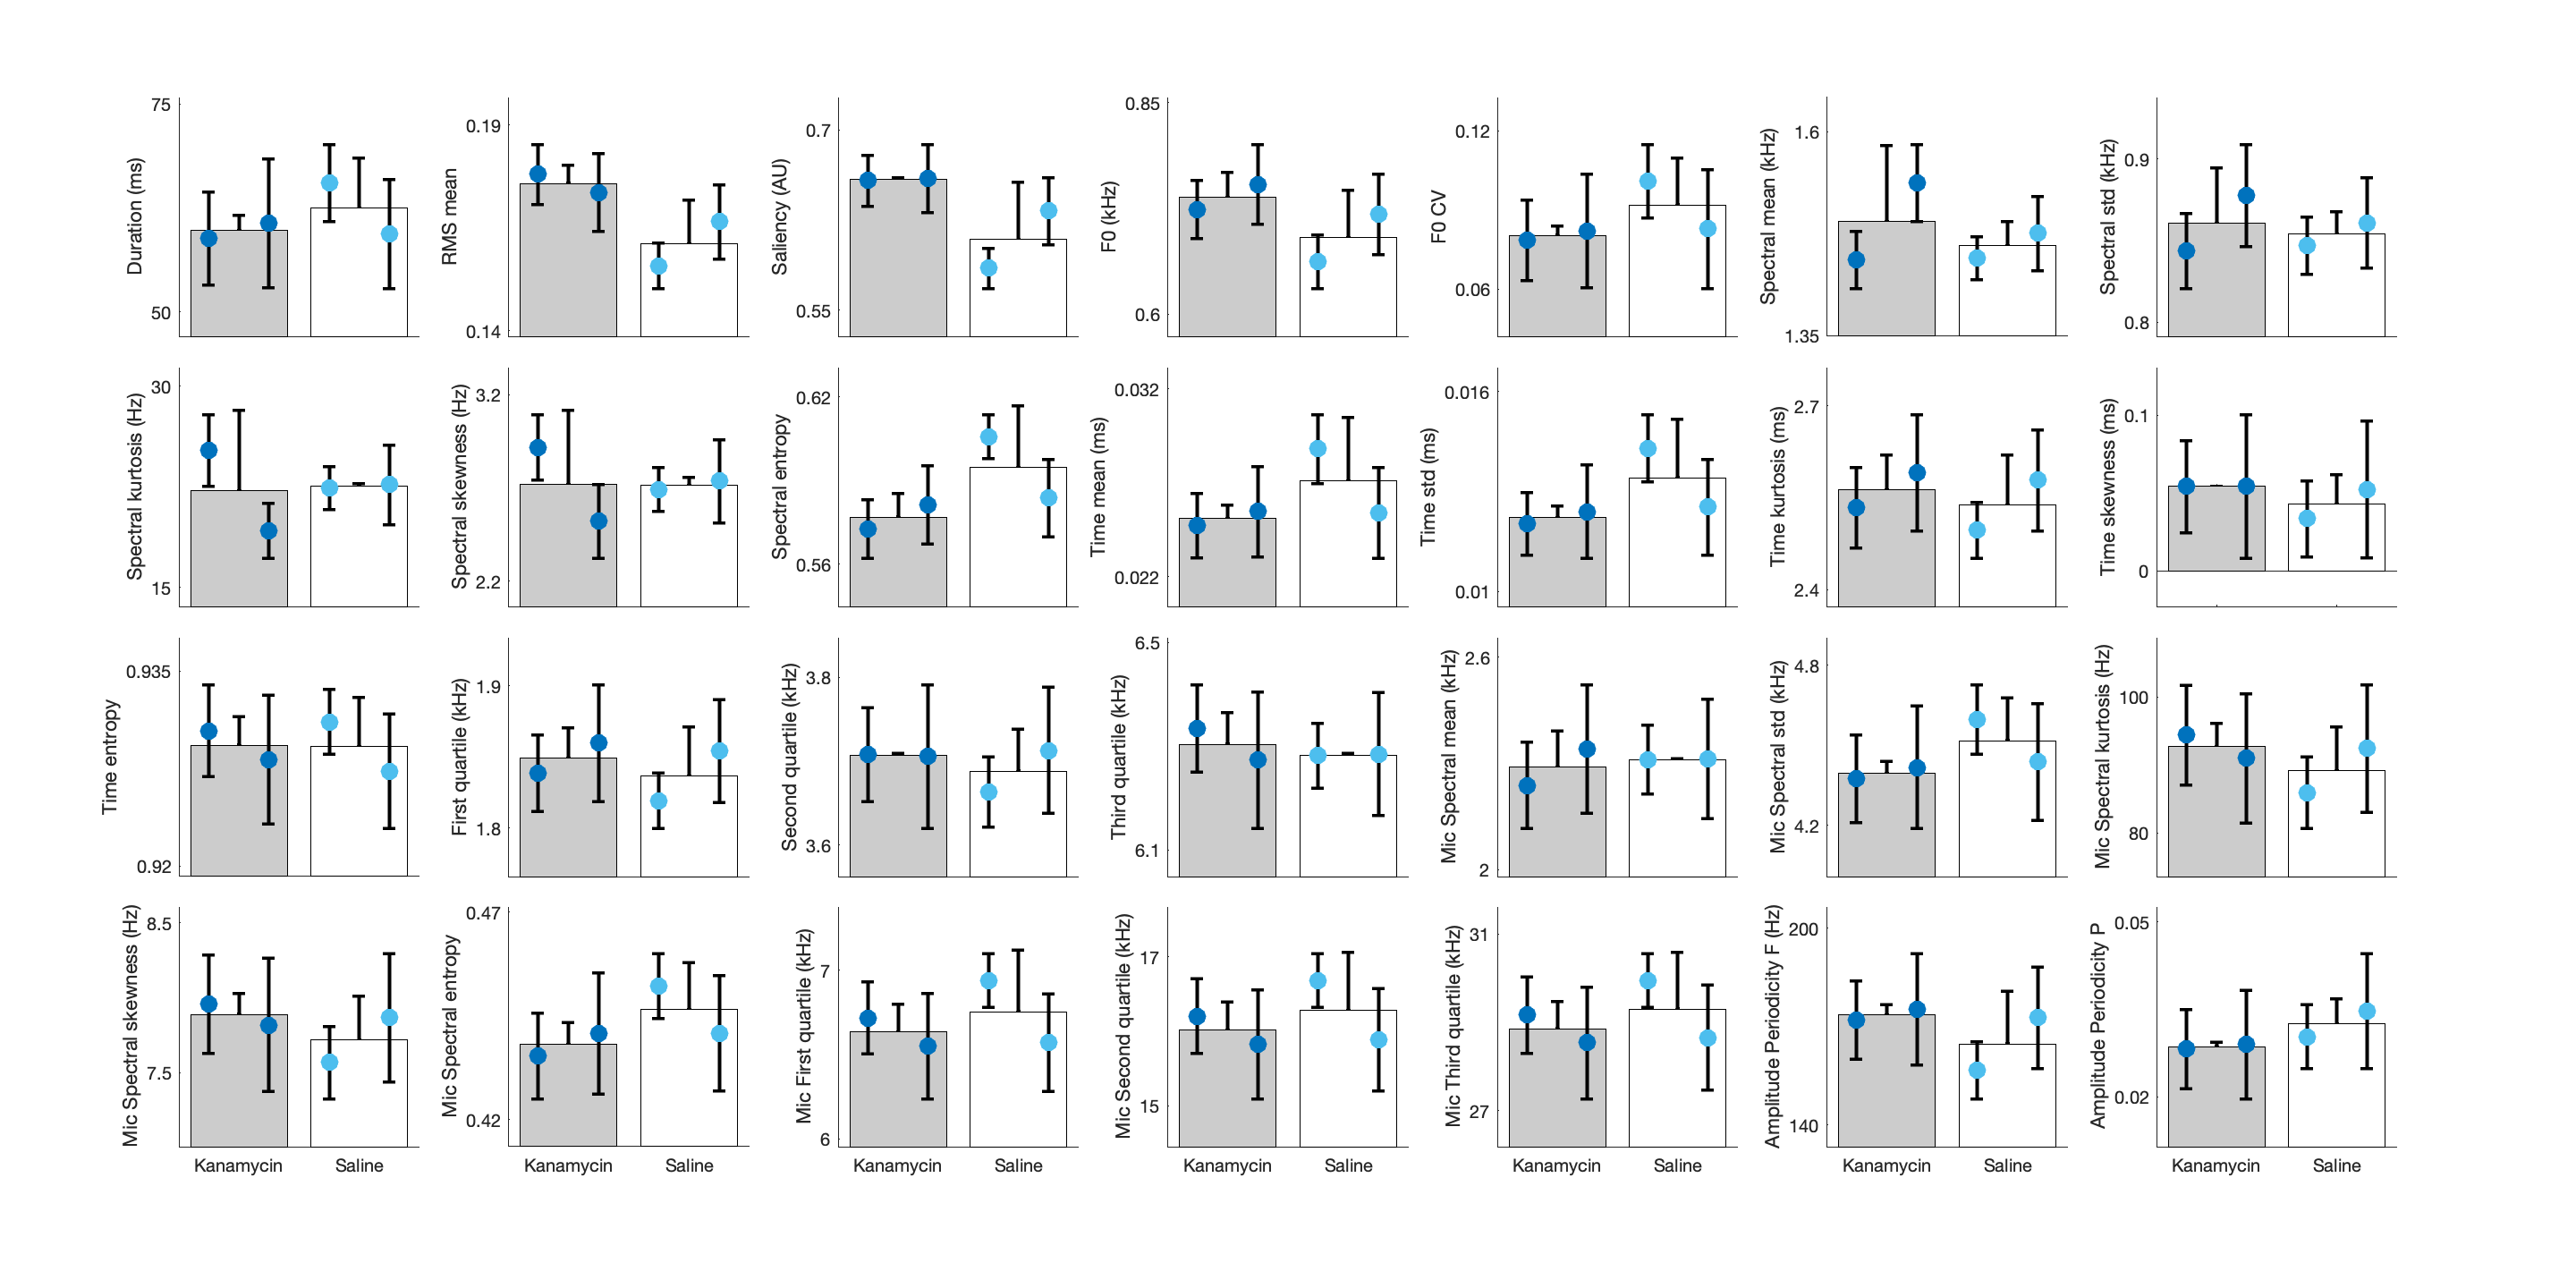

Fig1.Units = 'inches';
Fig1.Position(3:4) = [20 10];
Fig1.PaperSize = [20 10];

print(Fig1,fullfile(Path2Paper,'SupFigure14_PAF_MalesAcGroup2.pdf'),'-dpdf','-fillpage')

**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

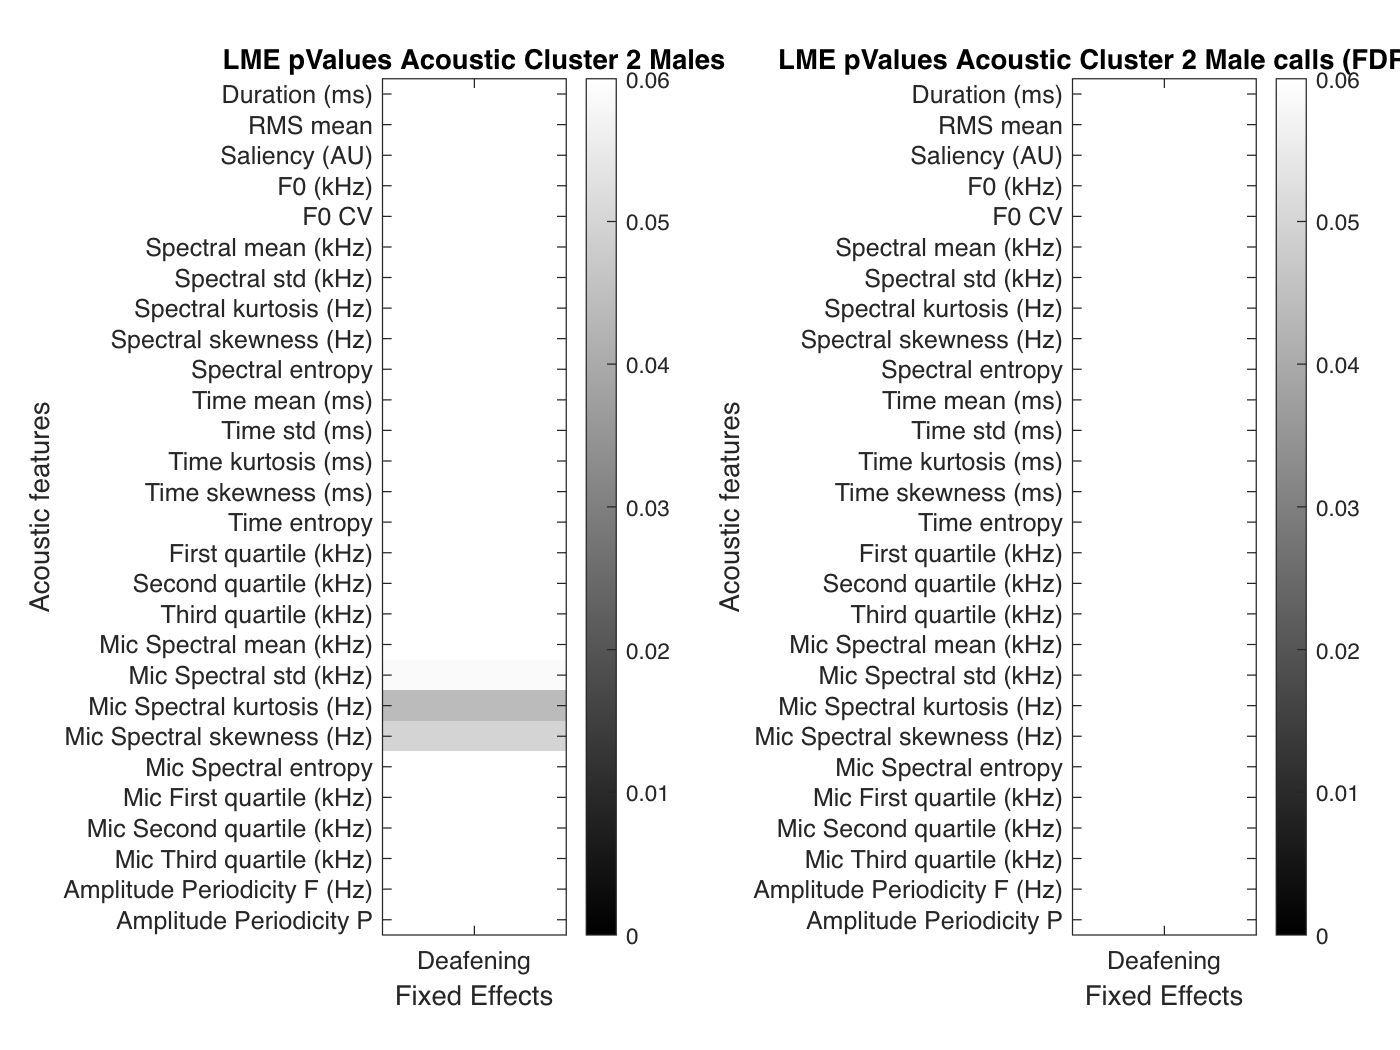

% Now correct these p-values for False discovery rate (True proba =
% p*(Num_comparisons-rank)) within each acoustic cluster
NVars = size(Pvalue_matrix_Post_hoc,1);

Pvalue_vector = Pvalue_matrix_Post_hoc;
NonNaNInd = ~isnan(Pvalue_vector);
[~,IndOrd]=sort(Pvalue_vector(NonNaNInd));
Ord = nan(size(IndOrd));
for ii=1:length(IndOrd)
    Ord(ii) = find(IndOrd==ii);
end
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
Pvalue_matrix_Post_hocFDR = Pvalue_vectorFDR;

figure()
tiledlayout(1,2)
nexttile
Im = imagesc(Pvalue_matrix_Post_hoc);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues Acoustic Cluster 2 Males')
nexttile
Im = imagesc(Pvalue_matrix_Post_hocFDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues Acoustic Cluster 2 Male calls (FDR corrected)')

Pvalue_matrix_Post_hoc

Pvalue_matrix_Post_hoc =     0.2132
    0.1553
    0.4299
    0.6302
    1.0000
    0.1476
    0.2286
    0.2356
    0.2965
    0.5998


PV_sig = Pvalue_matrix_Post_hoc(Pvalue_matrix_Post_hoc<0.05);
PV_postHoc_sig = Pvalue_matrix_Post_hocFDR(Pvalue_matrix_Post_hoc<0.05);
AcVarsSig = AcVars(Pvalue_matrix_Post_hoc<0.05);
for vv=1:length(AcVarsSig)
    fprintf(1,'%s %.4f  %.4f\n',AcVarsSig{vv},PV_sig(vv), PV_postHoc_sig(vv))
end

Mic Spectral kurtosis (Hz) 0.0439  1.1859
Mic Spectral skewness (Hz) 0.0498  1.2936
